%梯度下降-fitfuction(tune the numbers)
%linar function--y=x+1
%data:x=1...100;y=2...101

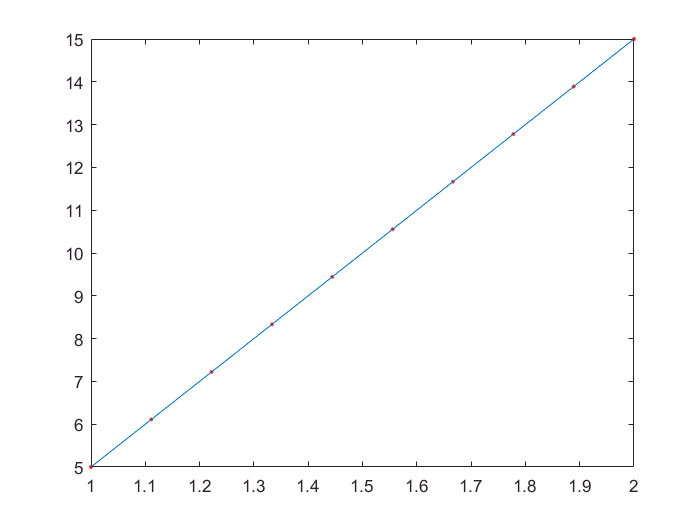

%不带冲量
A = linspace(1,2,10);
B = linspace(5,15,10);
W_old=random('Normal',0,1,1,1);
b_old=random('Normal',0,1,1,1);
belta=0.01;
i=0;
while(1)
    i=i+1;
    W_new=W_old+belta*sum((B-W_old.*A-b_old).*A);
    b_new=b_old+belta*sum(B-W_old.*A-b_old);
    Loss_old=1/2*sum((B-W_old.*A-b_old).^2);
    Loss_new=1/2*sum((B-W_new.*A-b_new).^2);
    W_old=W_new;
    b_old=b_new;
    if(Loss_new<exp(-20))
        break
    end
end

plot(A,B,'r.',A,(W_old.*A+b_old))

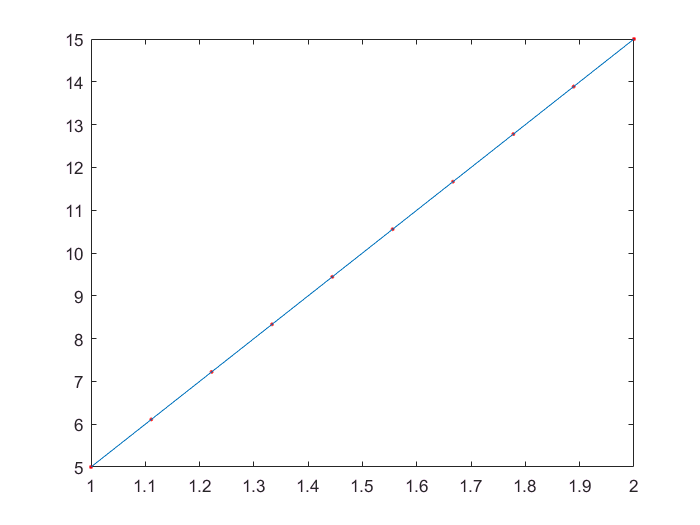

%带冲量
A = linspace(1,2,10);
B = linspace(5,15,10);
W_old=random('Normal',0,1,1,1);
b_old=random('Normal',0,1,1,1);
belta=1;
i=0;
while(1)
    i=i+1;
    W_new=W_old+belta*sum((B-W_old.*A-b_old).*A);
    b_new=b_old+belta*sum(B-W_old.*A-b_old);
    Loss_old=1/2*sum((B-W_old.*A-b_old).^2);
    Loss_new=1/2*sum((B-W_new.*A-b_new).^2);
    W_old=W_new;
    b_old=b_new;
    if(Loss_new<Loss_old)
        belta=2*belta;
    else
        belta=belta/2;
    end
    if(Loss_new<exp(-20))
        break
    end
end

plot(A,B,'r.',A,(W_old.*A+b_old))

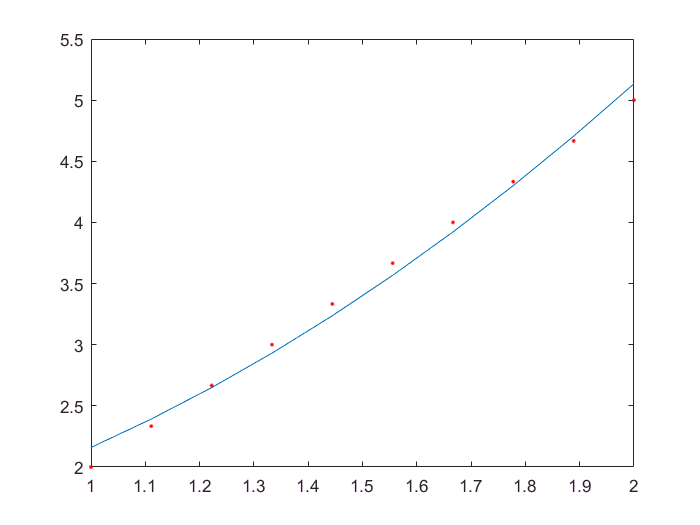

%exp
%带冲量
A = linspace(1,2,10);
B = linspace(2,5,10);
W_old=random('Normal',0,1,1,1);
b_old=random('Normal',0,1,1,1);
belta=0.003;
i=0;
while(1)
    i=i+1;
    W_new=W_old+belta*sum((B-W_old.*(A.^2)-b_old).*(A.^2));
    b_new=b_old+belta*sum(B-W_old.*(A.^2)-b_old);
    Loss_old=1/2*sum((B-W_old.*(A.^2)-b_old).^2);
    Loss_new=1/2*sum((B-W_new.*(A.^2)-b_new).^2);
    W_old=W_new;
    b_old=b_new;
%     if(Loss_new<Loss_old)
%     %if(sum(abs([W_new,b_new]-[W_old,b_old]))<0.02)
%         belta=belta*1.5
%     else
%         belta=belta*1.1
%     end

    if(Loss_new<exp(-4))
        break
    end
    
    if(i>6000)
        break
    end
   
end
plot(A,B,'r.',A,(W_old.*A.^2+b_old))

%second
% data
x = (1:100);
y = (2:101);

%theta1 = 0;     % 一次系数
%theta0 = 0;     % 常系数

v = 0.00001;    % 步长 元素个数小于9用0.0001也行

[row,col] = size(x);

% theta初始化  初值选取对结果影响也很大 特别是theta2的选取
theta1 = mean(y) / mean(x)
theta0 = y(1) - theta1 * x(1)

 while 1
     temp1 = 0;
     temp0 = 0;
     for i=1:col
         temp1 = temp1 + ((y(i) - (theta1*x(i) + theta0)) * x(i));
         temp0 = temp0 + ((y(i) - (theta1*x(i) + theta0)) * 1);
     end
     old_theta1 = theta1;
     old_theta0 = theta0;  
     theta1 = theta1 + v * temp1
     theta0 = theta0 + v * temp0
     temp1 = 0;    
     temp0 = 0;
     
     % 误差
     e = ((old_theta1 - theta1)^2 + (old_theta0 - theta0)^2)
     
     if  e < 0.000003       
         f = theta1 * x + theta0;
         plot(x,y,'r+',x,f)
         break;
     end
 end

